clc; clear; close all;

- Agregue un controlador en espacio de estados al sistema del ejercicio 3.

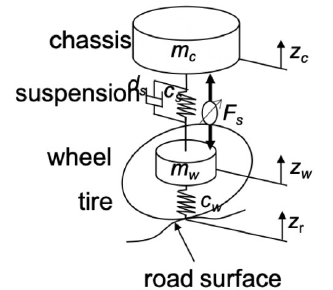

% Model parameters
%---------------------------------------------------
mc  = 401;                         % Quarter car mass [kg]
mw  = 48;                          % Wheel mass [kg]
ds  = 2200;                        % Suspension damping coefficient [Ns/m]
cs  = 23000;                       % Suspension spring coefficient [N/m]
cw  = 250000;                      % Wheel spring coefficient [N/m]
tau = 0.001;                       % Actuator time constant [s]
run("active_suspension_ctrl_design.m"); 

- Varíe en un 10% al menos 3 parámetros del modelo y en 5% los restantes 3 parámetros.

xmcObs  = 0.9; % Quarter car mass [kg]
xmwObs  = 0.9; % Wheel mass [kg]
xdsObs  = 0.9; % Suspension damping coefficient [Ns/m]
xcsObs  = 0.9; % Suspension spring coefficient [N/m]
xcwObs  = 0.9; % Wheel spring coefficient [N/m]
xtauObs = 0.9; % Actuator time constant [s]

mc  = xmcObs*mc;
mw  = xmwObs*mw; 
ds  = xdsObs*ds;
cs  = xcsObs*cs;
cw  = xcwObs*cw;
tau = xtauObs*tau;

Aobs = [[0 1 0 0 0];[-(cw+cs)/mw -ds/mw cs/mw ds/mw -1/mw];[0 0 0 1 0];[cs/mc ds/mc -cs/mc -ds/mc 1/mc];[0 0 0 0 -1/tau]];
Bobs = [0 0 0 0 1/tau]';
Hobs = [0 cw/mw 0 0 0]';
Cobs = [[-1 0 1 0 0];[cs/mc ds/mc -cs/mc -ds/mc 1/mc]];
Cobs = Cobs(1,:);

- Determine el polinomio deseado para un overshoot del 2% y un settling time de 0.5s para la variable de salida del sistema.

Es al pedo esto igual porque el sistema no es completamente controlable así que no podemos poner los polos donde queramos. Tenemos que utilizar LQR.

Mp      = 0.02;                     % overshoot
delta   = log(Mp);                  % decremento logaritmico
zeta    = 1/sqrt(1 + (pi/delta)^2); % amortiguamiento mínimo
Ts      = 0.5;                      % tiempo de asentamiento
wn      = -log(0.02)/(Ts*zeta);     % frecuencia natural
disp(zeta);

    0.7797



disp(wn);

   10.0346



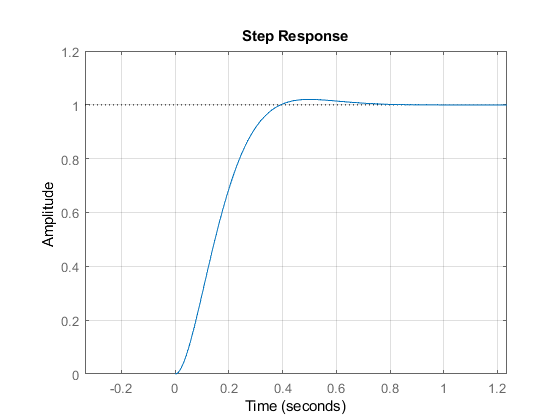

num     = wn^2;
den     = [1 2*zeta*wn wn^2];
sys     = tf(num, den);
step(sys); grid on; axis('equal')

stepinfo(sys)

ans = struct with fields:
        RiseTime: 0.2385
    SettlingTime: 0.3590
     SettlingMin: 0.9077
     SettlingMax: 1.0200
       Overshoot: 2.0000
      Undershoot: 0
            Peak: 1.0200
        PeakTime: 0.5003


- Agrege acción integral al controlador.

- Cierre el bucle de control a través del observador. Encuentre el valor de la matriz K.

- Determine el valor de kr.

- Grafique las variables de interés del sistema.

% Este sistema no era completamente controlable usamos LQR jeje
% No funciona con control integral para las dos variables de salida asi que
% probamos con poner control integral solamente para la compresión del
% amortiguador.
Aaug   = [Aobs          zeros(5, 1)
          Cobs              0      ];
Baug   = [Bobs; 0]

Baug = 	1.0e+03 *

         0
         0
         0
         0
    1.1111
         0


Caug   = [Cobs zeros(1, 1)]

Caug =     -1     0     1     0     0     0


y1max  = 0.05; % m
y2max  = 5;    % m/s^2
umax   = 1000; % N
alpha1 = 1;
alpha2 = 1;
rho    = 1;
%Qy     = [alpha1/y1max^2 0; 0 alpha2/y2max^2];
Qy     = [alpha1/y1max^2];
Qu     = rho/umax^2;
Qx     = Caug.'*Qy*Caug

Qx =   400.0000         0 -400.0000         0         0         0
         0         0         0         0         0         0
 -400.0000         0  400.0000         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0


K      = lqr(Aaug, Baug, Qx, Qu, 0)

Error using lqr (line 42)
Cannot compute the stabilizing Riccati solution S for the LQR design. 
This could be because: 
  * R is singular, 
  * [Q N;N' R] needs to be positive definite, 
  * The E matrix in the state equation is singular.

% Bueno, entonces aparecentemenre tampoco se peude. Antes de obtener la
% solución como la gente, vamos a probar las soluciones brutas.

- Definición de la realimentación y pre-alimentación.

Notar que definimos la matriz K sin tomar en cuenta como estado la integral del error en la compresión del amortiguador.

Qx     = Cobs.'*Qy*Cobs;
K      = lqr(Aobs, Bobs, Qx, Qu, 0)

K = 	1.0e+03 *

   -6.2784   -0.0046    8.0238    1.1192    0.0000


kr   = 1/(Cobs*(-(Aobs-Bobs*K)\Bobs))

kr = 2.8784e+04

% Cuando consideramos las dos salidas, la constante de pre-alimentación
% para la aceleració es nula. Esto nos esta diciendo que no podemos dar referencias
% de la aceleración en el chasis, solamente de la compresión del amortiguador.

- Definición del observador

Podemos utilizar la wn obtenida por las especificaciones para saber mas o menos donde poner los polos del observador.

z1 = 0.7;
p1 = -3*wn*(z1 + i*sqrt(1-z1^2))

p1 = -21.0728 - 21.4985i

z2 = 0.7;
p2 = -6*wn*(z2 + i*sqrt(1-z2^2))

p2 = -42.1455 - 42.9970i

p3 = -10*wn

p3 = -100.3465

p = [p1 p1' p2 p2' p3].'

p = 	1.0e+02 *

  -0.2107 - 0.2150i
  -0.2107 + 0.2150i
  -0.4215 - 0.4300i
  -0.4215 + 0.4300i
  -1.0035 + 0.0000i


L = place(A.', Cobs.', p); % En realidad se determina L^t
L = L.'

L = 	1.0e+10 *

    0.0000
   -0.0001
   -0.0000
    0.0000
   -3.3975


% Tampoco funca la solución así nomas así que seguimos después-+.